# LAB 2 - Bo Chang, Lin - MAT 275

# Exercise 1

A=[-2 8 -9;-5 -8 -8;4 -4 3];
B=[-5 3 9;-10 1 0;20 2 -2];
b=[3 -2 14]';
c=[2 0 1];
d=[1 4 1]';

### **Part (a)**

disp(A*B)

  -250   -16     0
   -55   -39   -29
    80    14    30


disp(B*A)

    31  -100    48
    15   -88    82
   -58   152  -202


disp(c*A)

     0    12   -15


disp(B*d)

    16
    -6
    26


### **Part (b)**

C=[A;B]

C =     -2     8    -9
    -5    -8    -8
     4    -4     3
    -5     3     9
   -10     1     0
    20     2    -2


D=[B d]

D =     -5     3     9     1
   -10     1     0     4
    20     2    -2     1


### Part (c)

syms x y z
disp(A*[x y z]' == b)  

$$\left(\begin{array}{c} 8\,\bar{y}-2\,\bar{x}-9\,\bar{z}=3\\ -5\,\bar{x}-8\,\bar{y}-8\,\bar{z}=-2\\ 4\,\bar{x}-4\,\bar{y}+3\,\bar{z}=14 \end{array}\right)$$

disp([x y z]' == inv(A)*b)                                               % Method 1

$$\left(\begin{array}{c} \bar{x}=\frac{524}{123}\\ \bar{y}=-\frac{295}{492}\\ \bar{z}=-\frac{223}{123} \end{array}\right)$$

format rational                             
disp(A\b)                                                                % Method 2

     524/123   
    -295/492   
    -223/123   


format default
disp(A\b)

    4.2602
   -0.5996
   -1.8130



### Part (d)

A(1,1)=0;
disp(A)

     0     8    -9
    -5    -8    -8
     4    -4     3



### Part (e)

a=A(2,:)

a =     -5    -8    -8


### Part (f)

B(:,1)=[]

B =      3     9
     1     0
     2    -2


# Exercise 2

### Part (a)

Display contents of geomsum1 M-file

type 'Lab2_Ex2_geomsum1' % here I renamed it for file sorting purpuse

function S = Lab2_Ex2_geomsum1(commRatio,a_1st,n_term)

S=0;

for i = 0:1:n_term-1
    S = S + a_1st*commRatio^i;
end


Assign values to input variables

r = -7/9;
a = 3;
n = 12;

Compute geometric sum for specified values of r,a, and n.

format default
S1 = Lab2_Ex2_geomsum1(r,a,n) 

S1 = 1.6048

### Part (b)

type 'Lab2_Ex2_geomsum2'

function Lab2_Ex2_geomsum2(r,a,n)

sum(a*ones(1,n).*(r.^(0:n-1)))

end


Lab2_Ex2_geomsum2(r,a,n)

ans = 1.6048

# Exercise 3

### Part (a)

Initiate product P.

P = 1;

Define starting iteration index.

m = 1;

Define stepsize of iteration.

k = 2;

Define ending iteration index.

n = 1+2*8;

Compute product.

for i = m:k:n 
    P=P*i;    % muliply P by next element at each iteration (suppress output)
end

Display product.

disp(P)

    34459425



### Part (b)

P = prod(1:2:17) % Single command

P = 34459425

# Exercise 4

Initiate variables.

power = 3;
k = 1;                % initiate counter

Initialize the vector v to the empty vector

v = [];

Compute powers and store in v.

while power < 10^5    % specify condition of while-loop: stop iterating once 
                      % condition is no longer satisfied
    v(k) = power;     % evaluate kth entry of the vector  v 
    k = k + 1;        % increment counter k
    power = 3^k;      % compute next value of power at each iteration
end

Display vector v.

disp(v)

           3           9          27          81         243         729        2187        6561       19683       59049



disp(v')

           3
           9
          27
          81
         243
         729
        2187
        6561
       19683
       59049



3^size(v,2) < 10^5 & 10^5 < 3^(size(v,2)+1)     % Check result

ans = logical
   1


# Exercise 5

 Display contents of function f M-file.

type 'Lab2_Ex5_f.m'      % here I renamed it for file sorting purpuse

function y = Lab2_Ex5_f(x)

if x <= 5
    y = 2-x;
elseif (5 < x) && (x <= 10)
    y = exp(x-13);
elseif x == 13
    y = "the function is undefined at x = 13";
else
    y = x./(x-13);
end

end


Evaluate f at the given vaue of x.

 Lab2_Ex5_f(4)

ans = -2

Evaluate f at the given value of x. 

Lab2_Ex5_f(5)

ans = -3

% Evaluate f at the given value of x.

Lab2_Ex5_f(5.5)

ans = 5.5308e-04

Evaluate f at the given value of x.

Lab2_Ex5_f(10)

ans = 0.0498

Evaluate f at the given value of x.

Lab2_Ex5_f(13)

ans = "the function is undefined at x = 13"

Evaluate f at the given value of x.

Lab2_Ex5_f(14)

ans = 14

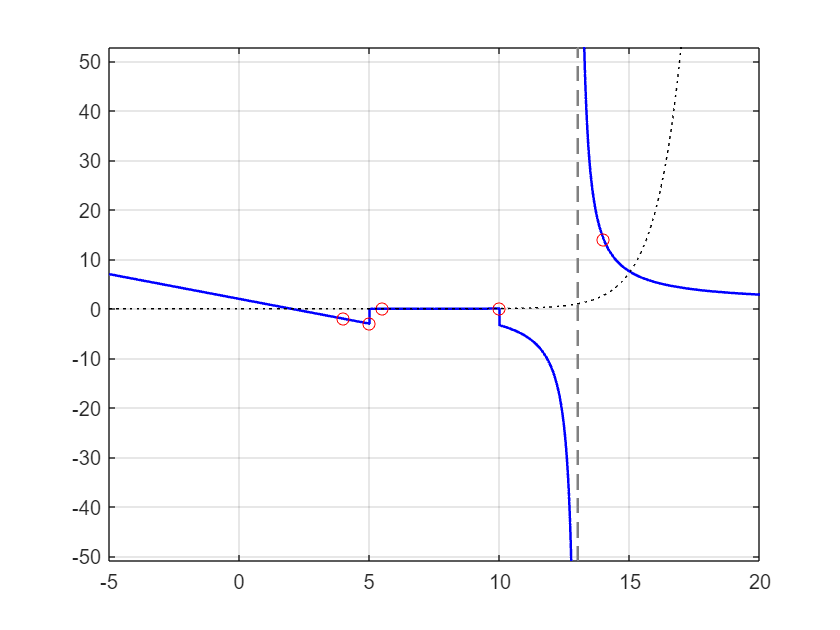

% Supplementary figure
syms x
y = piecewise(x <= 5,2-x,5 < x <= 10,exp(x-13),x > 10 & x~=13,x./(x-13));
fplot(y,[-5 20],"b","LineWidth",1.25)
grid on
hold on

for i = [4 5 5.5 10 14]
    plot(i,Lab2_Ex5_f(i),"ro")
end

fplot(exp(x-13),"k:")
% fplot(x./(x-13),"y-.")

hold off